**Дополнительная задача**

**Топольницкий А.**

**Вариант 53**

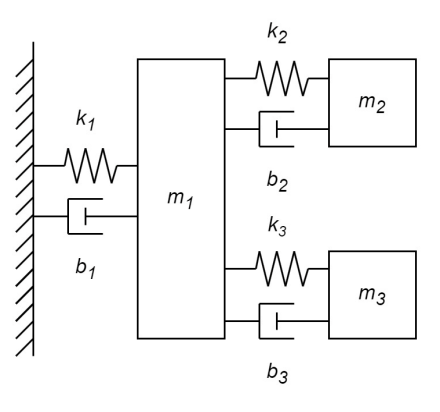

**Аналитическое моделирование**

Функцию Лагранжа для всей системы можно записать в следующем виде:

$$L = L_1 + L_2 = K_1-P_1 + K_2-P_2+K_3-P_3$, где

$$L_1 = \frac{1}{2}m_1\dot{x_1}^2 - (\frac{1}{2}k_1x_1^2 + \frac{1}{2}k_2[x_1-x_2]^2+\frac{1}{2}k_3[x_1-x_3]^2)$$, 

$$L_2 = \frac{1}{2}m_2\dot{x_2}^2 -  \frac{1}{2}k_2[x_1-x_2]^2$$,


$$$L_3 = \frac{1}{2}m_3\dot{x_3}^2 -  \frac{1}{2}k_3[x_1-x_3]^2$$$


Уравнения Эйлера-Лагранжа для механической системы можно записать в виде

$$\frac{d}{dt}\Big(\frac{\partial L}{\partial \dot{x}}\Big) - \frac{\partial L}{\partial {x}}= Q$$, где $Q$ - внешняя сила

$$\frac{d}{dt}\Big(\frac{\partial L_1}{\partial \dot{x}_1}\Big) = m\ddot{x}_1$$,

 $$\frac{\partial L_1}{\partial x_1} =-k_1x_1 - k_2[x_1-x_2]-k_3[x_1-x_3]$$,

 
$$$Q_1 = -b_1 \dot{x}_1 - b_2[\dot{x}_1-\dot{x}_2]-b_3[\dot{x}_1-\dot{x}_3] $$$


$$\frac{d}{dt}\Big(\frac{\partial L_2}{\partial \dot{x}_2}\Big) = m\ddot{x}_2$$, $$\frac{\partial L_2}{\partial x_2} =k_2[x_1-x_2]$$, $$Q_2 =  b_2[\dot{x}_1-\dot{x}_2] $$,

$$\frac{d}{dt}\Big(\frac{\partial L_3}{\partial \dot{x}_3}\Big) = m\ddot{x}_3$$, $$\frac{\partial L_3}{\partial x_3} =k_3[x_1-x_3]$$, $$Q_3 =  b_3[\dot{x}_1-\dot{x}_3] $$,

Тогда итоговую систему можно переписать так


$$$\left\{\begin{array}{@{}ll@{}} m\ddot{x}_1 = -k_1x_1 - k_2[x_1-x_2]-k_3[x_1-x_3]-b_1 \dot{x}_1 - b_2[\dot{x}_1-\dot{x}_2]-b_3[\dot{x}_1-\dot{x}_3]  \\ m\ddot{x}_2 =k_2[x_1-x_2]+b_2[\dot{x}_1-\dot{x}_2] \\ m\ddot{x}_3 =k_3[x_1-x_3]+b_3[\dot{x}_1-\dot{x}_3]  \end{array}\right.$$$


Задание начальных данных:

clc; clear all;
m1 = 3.7; m2 = 12; m3 = 20.8; % kg 
b1 = 25.13851; b2 = 10; b3 = 12.24894; % N/(m/s)
k1 = 228.5319; k2 = 182.9234; k3 = 81.65957; % N/m
x1_0 = 1; x2_0 = 2; x3_0 = 3; % m

F_1 = 0; F_2 = 10; F_3 = 10; % N
time_F_1 = 0.5; time_F_2 = 0.5; time_F_3 = 0.5; % s
t = 20;
x1 = [x1_0; 2 * x1_0; 5 * x1_0];
x2 = [x2_0; 2 * x2_0; 5 * x2_0];
x3 = [x3_0; 2 * x3_0; 5 * x3_0];

Задача данных в лайв-скрипт

Lab11
lab11sm
F_1 = 0; F_2 = 0; F_3 = 0;
x1_0 = x1(1); x2_0 = x2(1); x3_0 = x3(1);

sim11 = sim('Lab11');
sims1 = sim('lab11sm');

x1_0 = x1(2); x2_0 = x2(2); x3_0 = x3(2);
sim12 = sim('Lab11');
sims2 = sim('lab11sm');

x1_0 = x1(3); x2_0 = x2(3); x3_0 = x3(3);
sim13 = sim('Lab11');
sims3 = sim('lab11sm');

x1_0 = x1(1); x2_0 = x2(1); x3_0 = x3(1); F_1 = 100; F_2 = 200; F_3 = 300;
sim14 = sim('Lab11');
sims4 = sim('lab11sm');

Сравнение Simulink и Simscape

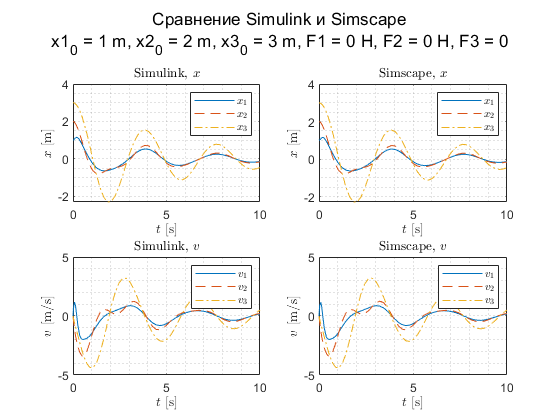

figure;
subplot(2,2,1)
plot(sim11.simout.x1.time, sim11.simout.x1.data)
grid minor
hold on
plot(sim11.simout.x2.time, sim11.simout.x2.data,'LineStyle','--')
plot(sim11.simout.x3.time, sim11.simout.x3.data,'LineStyle','-.')
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simulink, $x$', 'Interpreter',"latex")
subplot(2,2,3)
plot(sim11.simout.dx1.time, sim11.simout.dx1.data)
grid minor
hold on
plot(sim11.simout.dx2.time, sim11.simout.dx2.data,'LineStyle','--')
plot(sim11.simout.dx3.time, sim11.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simulink, $v$', 'Interpreter',"latex")


subplot(2,2,2)
plot(sims1.simout.x1.time, sims1.simout.x1.data)
hold on
plot(sims1.simout.x2.time, sims1.simout.x2.data,'LineStyle','--')
plot(sims1.simout.x3.time, sims1.simout.x3.data,'LineStyle','-.')
grid minor
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simscape, $x$', 'Interpreter',"latex")

subplot(2,2,4)
plot(sims1.simout.dx1.time, sims1.simout.dx1.data)
hold on
plot(sims1.simout.dx2.time, sims1.simout.dx2.data,'LineStyle','--')
plot(sims1.simout.dx3.time, sims1.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simscape, $v$', 'Interpreter',"latex")
grid minor
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(1)),' m, x2_0 = ', num2str(x2(1)), ...
    ' m, x3_0 = ', num2str(x3(1)),' m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

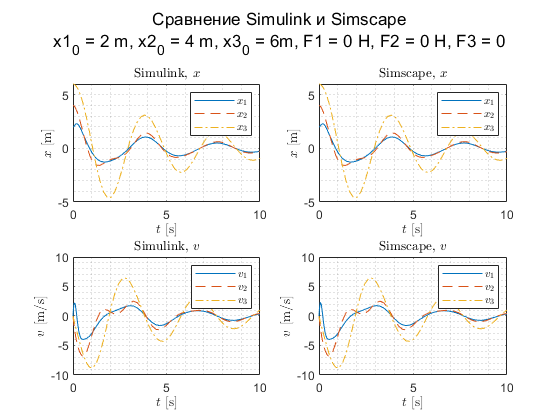


figure;
subplot(2,2,1)
plot(sim12.simout.x1.time, sim12.simout.x1.data)
grid minor
hold on
plot(sim12.simout.x2.time, sim12.simout.x2.data,'LineStyle','--')
plot(sim12.simout.x3.time, sim12.simout.x3.data,'LineStyle','-.')
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simulink, $x$', 'Interpreter',"latex")
subplot(2,2,3)
plot(sim12.simout.dx1.time, sim12.simout.dx1.data)
grid minor
hold on
plot(sim12.simout.dx2.time, sim12.simout.dx2.data,'LineStyle','--')
plot(sim12.simout.dx3.time, sim12.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simulink, $v$', 'Interpreter',"latex")


subplot(2,2,2)
plot(sims2.simout.x1.time, sims2.simout.x1.data)
hold on
plot(sims2.simout.x2.time, sims2.simout.x2.data,'LineStyle','--')
plot(sims2.simout.x3.time, sims2.simout.x3.data,'LineStyle','-.')
grid minor
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simscape, $x$', 'Interpreter',"latex")

subplot(2,2,4)
plot(sims2.simout.dx1.time, sims2.simout.dx1.data)
hold on
plot(sims2.simout.dx2.time, sims2.simout.dx2.data,'LineStyle','--')
plot(sims2.simout.dx3.time, sims2.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simscape, $v$', 'Interpreter',"latex")
grid minor
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(2)),' m, x2_0 = ', num2str(x2(2)), ...
    ' m, x3_0 = ', num2str(x3(2)),'m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

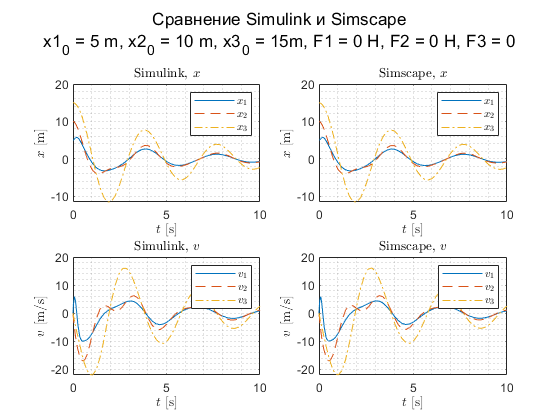


figure;
subplot(2,2,1)
plot(sim13.simout.x1.time, sim13.simout.x1.data)
grid minor
hold on
plot(sim13.simout.x2.time, sim13.simout.x2.data,'LineStyle','--')
plot(sim13.simout.x3.time, sim13.simout.x3.data,'LineStyle','-.')
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simulink, $x$', 'Interpreter',"latex")
subplot(2,2,3)
plot(sim13.simout.dx1.time, sim13.simout.dx1.data)
grid minor
hold on
plot(sim13.simout.dx2.time, sim13.simout.dx2.data,'LineStyle','--')
plot(sim13.simout.dx3.time, sim13.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simulink, $v$', 'Interpreter',"latex")


subplot(2,2,2)
plot(sims3.simout.x1.time, sims3.simout.x1.data)
hold on
plot(sims3.simout.x2.time, sims3.simout.x2.data,'LineStyle','--')
plot(sims3.simout.x3.time, sims3.simout.x3.data,'LineStyle','-.')
grid minor
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simscape, $x$', 'Interpreter',"latex")

subplot(2,2,4)
plot(sims3.simout.dx1.time, sims3.simout.dx1.data)
hold on
plot(sims3.simout.dx2.time, sims3.simout.dx2.data,'LineStyle','--')
plot(sims3.simout.dx3.time, sims3.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simscape, $v$', 'Interpreter',"latex")
grid minor
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(3)),' m, x2_0 = ', num2str(x2(3)), ...
    ' m, x3_0 = ', num2str(x3(3)),'m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

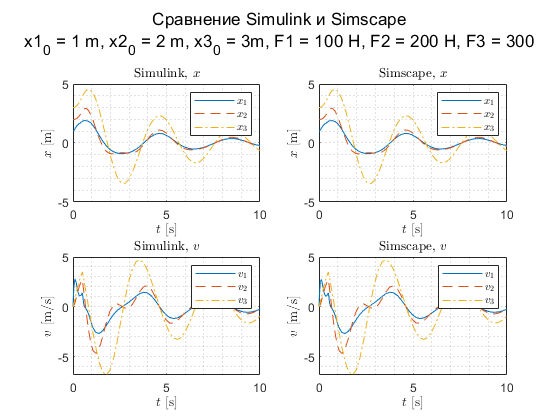


figure;
subplot(2,2,1)
plot(sim14.simout.x1.time, sim14.simout.x1.data)
grid minor
hold on
plot(sim14.simout.x2.time, sim14.simout.x2.data,'LineStyle','--')
plot(sim14.simout.x3.time, sim14.simout.x3.data,'LineStyle','-.')
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simulink, $x$', 'Interpreter',"latex")
subplot(2,2,3)
plot(sim14.simout.dx1.time, sim14.simout.dx1.data)
grid minor
hold on
plot(sim14.simout.dx2.time, sim14.simout.dx2.data,'LineStyle','--')
plot(sim14.simout.dx3.time, sim14.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simulink, $v$', 'Interpreter',"latex")


subplot(2,2,2)
plot(sims4.simout.x1.time, sims4.simout.x1.data)
hold on
plot(sims4.simout.x2.time, sims4.simout.x2.data,'LineStyle','--')
plot(sims4.simout.x3.time, sims4.simout.x3.data,'LineStyle','-.')
grid minor
legend('$x_1$','$x_2$','$x_3$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$x$ [m]','Interpreter',"latex")
title('Simscape, $x$', 'Interpreter',"latex")

subplot(2,2,4)
plot(sims4.simout.dx1.time, sims4.simout.dx1.data)
hold on
plot(sims4.simout.dx2.time, sims4.simout.dx2.data,'LineStyle','--')
plot(sims4.simout.dx3.time, sims4.simout.dx3.data,'LineStyle','-.')
legend('$v_1$','$v_2$','$v_3$', 'interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$v$ [m/s]','Interpreter',"latex")
title('Simscape, $v$', 'Interpreter',"latex")
grid minor
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(1)),' m, x2_0 = ', num2str(x2(1)), ...
    ' m, x3_0 = ', num2str(x3(1)),'m, F1 = ', num2str(100), ' H, F2 = ', num2str(200), ' H, F3 = ', num2str(300)]})

Усилия на пружинах и демпферах

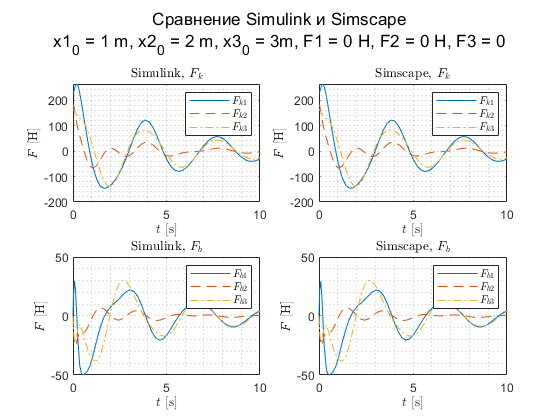

figure;
subplot(2,2,1)
plot(sim11.simout.k1.time, sim11.simout.k1.data)
hold on
grid minor
plot(sim11.simout.k2.time, sim11.simout.k2.data,'LineStyle','--')
plot(sim11.simout.k3.time, sim11.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_k$', 'Interpreter',"latex")

subplot(2,2,3)
plot(sim11.simout.d1.time, sim11.simout.d1.data)
hold on
grid minor
plot(sim11.simout.d2.time, sim11.simout.d2.data,'LineStyle','--')
plot(sim11.simout.d3.time, sim11.simout.d3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_b$', 'Interpreter',"latex")
subplot(2,2,2)
plot(sims1.simout.k1.time, sims1.simout.k1.data)
hold on
grid minor
plot(sims1.simout.k2.time, sims1.simout.k2.data,'LineStyle','--')
plot(sims1.simout.k3.time, sims1.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_k$', 'Interpreter',"latex")
subplot(2,2,4)
plot(sims1.simout.b1.time, sims1.simout.b1.data)
hold on
grid minor
plot(sims1.simout.b2.time, sims1.simout.b2.data,'LineStyle','--')
plot(sims1.simout.b3.time, sims1.simout.b3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_b$', 'Interpreter',"latex")
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(1)),' m, x2_0 = ', num2str(x2(1)), ...
    ' m, x3_0 = ', num2str(x3(1)),'m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

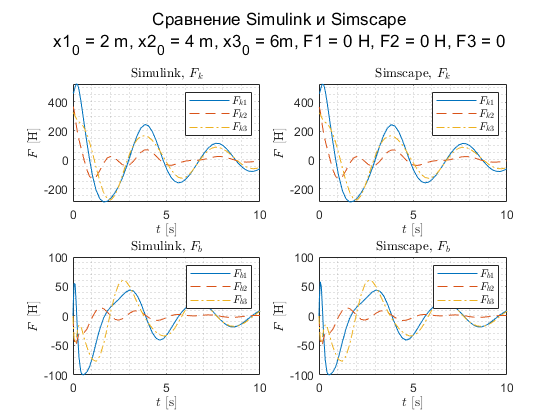


figure;
subplot(2,2,1)
plot(sim12.simout.k1.time, sim12.simout.k1.data)
hold on
grid minor
plot(sim12.simout.k2.time, sim12.simout.k2.data,'LineStyle','--')
plot(sim12.simout.k3.time, sim12.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_k$', 'Interpreter',"latex")

subplot(2,2,3)
plot(sim12.simout.d1.time, sim12.simout.d1.data)
hold on
grid minor
plot(sim12.simout.d2.time, sim12.simout.d2.data,'LineStyle','--')
plot(sim12.simout.d3.time, sim12.simout.d3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_b$', 'Interpreter',"latex")
subplot(2,2,2)
plot(sims2.simout.k1.time, sims2.simout.k1.data)
hold on
grid minor
plot(sims2.simout.k2.time, sims2.simout.k2.data,'LineStyle','--')
plot(sims2.simout.k3.time, sims2.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_k$', 'Interpreter',"latex")
subplot(2,2,4)
plot(sims2.simout.b1.time, sims2.simout.b1.data)
hold on
grid minor
plot(sims2.simout.b2.time, sims2.simout.b2.data,'LineStyle','--')
plot(sims2.simout.b3.time, sims2.simout.b3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_b$', 'Interpreter',"latex")
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(2)),' m, x2_0 = ', num2str(x2(2)), ...
    ' m, x3_0 = ', num2str(x3(2)),'m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

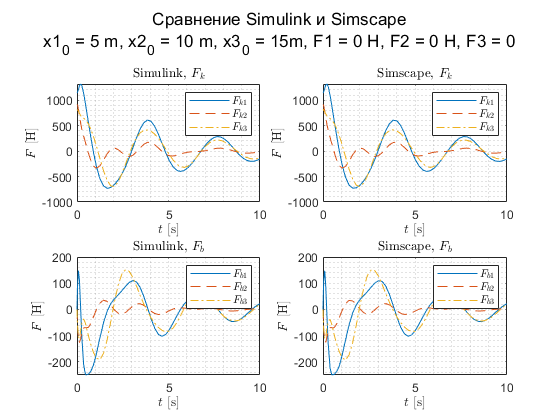


figure;
subplot(2,2,1)
plot(sim13.simout.k1.time, sim13.simout.k1.data)
hold on
grid minor
plot(sim13.simout.k2.time, sim13.simout.k2.data,'LineStyle','--')
plot(sim13.simout.k3.time, sim13.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_k$', 'Interpreter',"latex")

subplot(2,2,3)
plot(sim13.simout.d1.time, sim13.simout.d1.data)
hold on
grid minor
plot(sim13.simout.d2.time, sim13.simout.d2.data,'LineStyle','--')
plot(sim13.simout.d3.time, sim13.simout.d3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_b$', 'Interpreter',"latex")
subplot(2,2,2)
plot(sims3.simout.k1.time, sims3.simout.k1.data)
hold on
grid minor
plot(sims3.simout.k2.time, sims3.simout.k2.data,'LineStyle','--')
plot(sims3.simout.k3.time, sims3.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_k$', 'Interpreter',"latex")
subplot(2,2,4)
plot(sims3.simout.b1.time, sims3.simout.b1.data)
hold on
grid minor
plot(sims3.simout.b2.time, sims3.simout.b2.data,'LineStyle','--')
plot(sims3.simout.b3.time, sims3.simout.b3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_b$', 'Interpreter',"latex")
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(3)),' m, x2_0 = ', num2str(x2(3)), ...
    ' m, x3_0 = ', num2str(x3(3)),'m, F1 = ', num2str(0), ' H, F2 = ', num2str(0), ' H, F3 = ', num2str(0)]})

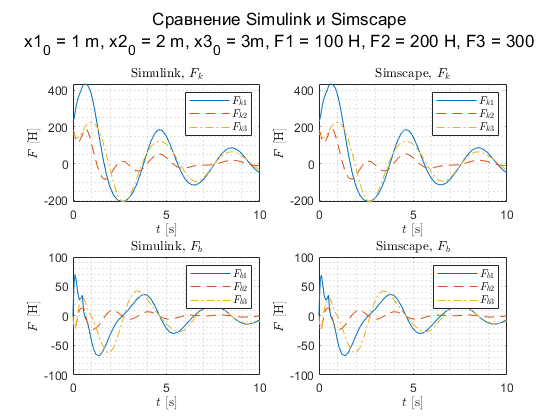


figure;
subplot(2,2,1)
plot(sim14.simout.k1.time, sim14.simout.k1.data)
hold on
grid minor
plot(sim14.simout.k2.time, sim14.simout.k2.data,'LineStyle','--')
plot(sim14.simout.k3.time, sim14.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_k$', 'Interpreter',"latex")

subplot(2,2,3)
plot(sim14.simout.d1.time, sim14.simout.d1.data)
hold on
grid minor
plot(sim14.simout.d2.time, sim14.simout.d2.data,'LineStyle','--')
plot(sim14.simout.d3.time, sim14.simout.d3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simulink, $F_b$', 'Interpreter',"latex")
subplot(2,2,2)
plot(sims4.simout.k1.time, sims4.simout.k1.data)
hold on
grid minor
plot(sims4.simout.k2.time, sims4.simout.k2.data,'LineStyle','--')
plot(sims4.simout.k3.time, sims4.simout.k3.data,'LineStyle','-.')
legend('$F_{k1}$','$F_{k2}$','$F_{k3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_k$', 'Interpreter',"latex")
subplot(2,2,4)
plot(sims4.simout.b1.time, sims4.simout.b1.data)
hold on
grid minor
plot(sims4.simout.b2.time, sims4.simout.b2.data,'LineStyle','--')
plot(sims4.simout.b3.time, sims4.simout.b3.data,'LineStyle','-.')
legend('$F_{b1}$','$F_{b2}$','$F_{b3}$','interpreter','latex')
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$F$ [H]','Interpreter',"latex")
title('Simscape, $F_b$', 'Interpreter',"latex")
sgtitle({['Сравнение Simulink и Simscape']; ['x1_0 = ', num2str(x1(1)),' m, x2_0 = ', num2str(x2(1)), ...
    ' m, x3_0 = ', num2str(x3(1)),'m, F1 = ', num2str(100), ' H, F2 = ', num2str(200), ' H, F3 = ', num2str(300)]})